clc
clear
close all

data = load('Data/ex1data2.txt');
X = data(:, 1:2); % regressors matrix
y = data(:, 3); % output
N = length(y); % number of training samples \ observations

% Print out some data points
fprintf('First 10 examples from the dataset: \n');

First 10 examples from the dataset: 


fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

 x = [2104 3], y = 399900 
 x = [1600 3], y = 329900 
 x = [2400 3], y = 369000 
 x = [1416 2], y = 232000 
 x = [3000 4], y = 539900 
 x = [1985 4], y = 299900 
 x = [1534 3], y = 314900 
 x = [1427 3], y = 198999 
 x = [1380 3], y = 212000 
 x = [1494 3], y = 242500 


STIMA UTILIZZANTO LEAST SQUARES NEL CASO MULTIVARIABILE

%% LEAST SQUARES
X = [ones(N,1), X]; 
% Minimizzo Funzione di Costo 
theta_hat = (transpose(X)*X)\transpose(X)*y; 
X = X(:, (2:3));


fprintf('Theta computed from the normal equations: \n');

Theta computed from the normal equations: 


fprintf(' %f \n', theta_hat);

 89597.909543 
 139.210674 
 -8738.019112 


fprintf('\n');

% Estimate the price of a 1650 sq-ft, 3 br house
price_hat = [1 1650 3]*theta_hat; 

fprintf(['Predicted price of a 1650 sq-ft, 3 br house ' ...
         '(using normal equations):\n $%f\n'], price_hat);

Predicted price of a 1650 sq-ft, 3 br house (using normal equations):
 $293081.464335


fprintf('\n');
fprintf('\n');

GRADIANT DESCENT MULTIVARIABLE CASE

%% NORMALIZZAZIONE REGRESSORI
[Z mu sigma] = featureNormalize(X); % normalize data

% Add intercept term to normalized data matrix Z
Xaug = [ones(N, 1), Z];

fprintf('Running gradient descent ...\n');

Running gradient descent ...


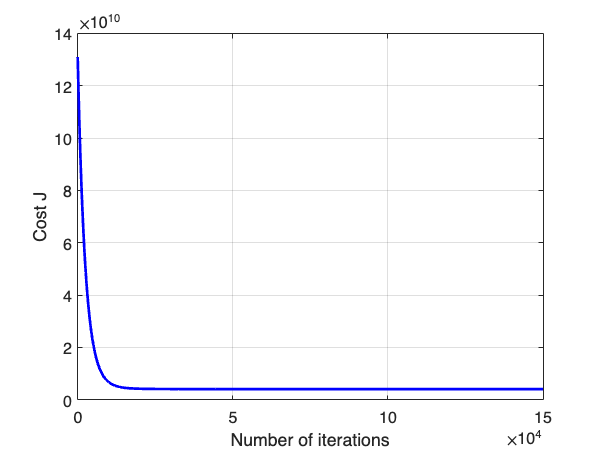


% Choose some alpha value
alpha = 0.0001;
num_iters = 150000;

% Init Theta and Run Gradient Descent 
theta_hat = zeros(3, 1);
[theta_hat, J_history] = gradientDescentMulti(Xaug, y, theta_hat, alpha, num_iters);

% Plot the convergence graph
figure;
plot(1:numel(J_history), J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J'); grid on;


% Display gradient descent's result
fprintf('Theta computed from gradient descent: \n');

Theta computed from gradient descent: 


fprintf(' %f \n', theta_hat);

 340412.659574 
 110630.906897 
 -6649.330895 


fprintf('\n');

% Estimate the price of a 1650 sq-ft, 3 br house
% Recall that the first column of X is all-ones. Thus, it does
% not need to be normalized.

z = ([1650 3] - mu)./sigma; % now you should work with normalized data
z = [1 z]; % add dummy regressor for intercept term to normalized data
price_hat = z*theta_hat ;  % estimated price


fprintf(['Predicted price of a 1650 sq-ft, 3 br house ' ...
         '(using gradient descent):\n $%f\n'], price_hat);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $293081.495536


function [Phi_norm, mu, sigma] = featureNormalize(X)
Phi_norm = X;

mu = zeros(1, size(X, 2));
sigma = zeros(1, size(X, 2));
mu = mean(X);
mu_vec = ones(size(X,1),2).*mu;

sigma = std(X);
sigma_vec = ones(size(X,1),2).*sigma;

Phi_norm(:,1) = (X(:,1)-mu_vec(:,1))./sigma(:,1);
Phi_norm(:,2) = (X(:,2)-mu_vec(:,2))./sigma(:,2);
%Phi_norm1 = normalize(X)
end


function [theta, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters)
N = length(y); % number of training examples
J_history = zeros(num_iters, 1);

for iter = 1:num_iters    
    for i = 1:length(theta)
        theta(i,1) = theta(i,1) - alpha*((-2/N)*transpose(X(:,i))*(y-X*theta));
        J_history(iter) = computeCostMulti(X, y, theta);
    end

end
end


function J = computeCostMulti(X, y, theta)
N = length(y); 
J = 0;

J = (1/N)*(transpose(y-X*theta)*(y-X*theta));
end